# Position and Attitude Control of a Quadcopter

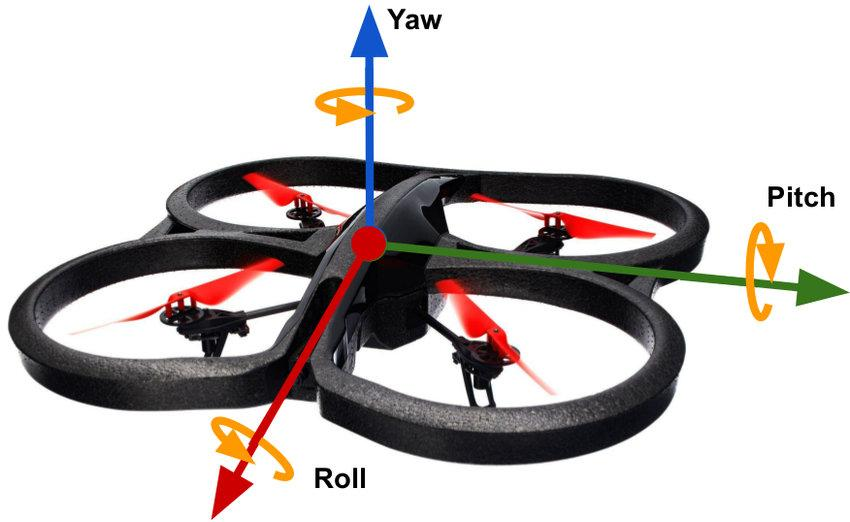

## Nomenclature

	Inertial frame								$\bar{N} = \{\hat{x}_N, \hat{y}_N, \hat{z}_N\}$

	Body frame								$\bar{B} = \{\hat{x}_B, \hat{y}_B, \hat{z}_B\}$

	Thrust constant							$K_t  \; [kg\cdot m\;/\;rad]$

	Body mass								$mass \; [kg]$

	Gravity constant							$g \; [m/s^2]$

	Wing length								$l \; [m]$

	Hover Throttle		 					 	$h_t \; [rad/s]$	

	Inertia matrix								$I_b \; [kg \cdot m^2]$

	Propeller Thrust vector						$T_p \; [N]$ 

	Propeller Torque vector						$\tau_p \; [N\cdot m]$

	Position vector							$r  \; [m]$ 

	Velocity vector 							$\dot{r} \; [m/s]$

	Attitude of Body as Euler Angles	 			$q \; [rad]$

	Rotational velocity of Body w.r.t Inertial frame	$\omega \; [rad/s]$

	Attitude of Body as DCM 					$R_{BN} = R_{NB}^T$

*	Reference* Position to Reference Attitude 		$T_k$

	Reference Attitude to acuators 				$\tau_k$

***pre-superscript denotes the frame a vector is defined in***

## Parameters

close all; clear;
%	Approximated based on hardware (DJI F-450 frame w/ 10in propellers) 
l = 0.23;
g = 9.81;
Kt = 0.02;
mass = 0.025;
Ixx = 4e-3;
Iyy = 4e-3;
Izz = 7e-3;
Ib = diag([Ixx Iyy Izz]);
ht = sqrt(g * mass / (Kt * 4));
d = -1e-3 * diag([1 1 1.75]);

## Dynamics

### Kinematics

	
$$T_k = \pmatrix{0 & -1 & 0 & 1 \cr -1 & 0 & 1 & 0 \cr 1 & 1 & 1 & 1}$$
 

        
$$\tau_k = \pmatrix{1 & 0 & -1 & 0 \cr 0 & -1 & 0 & 1 \cr -1 & 1 & -1 & 1}$$
 

### Forces

	
$$^NT_p = R_{NB}\;\hat{z}_{B}\; K_t \Sigma^4_{i=1}u_i^2$$


	
$$^B\tau_p = K_t \;l\;\tau_k\;u^Tu$$


	
$$^NF_g = -massg \hat{z}_N$$


	
$$^NF_w = w_1\hat{x}_N + w_2\hat{y}_N + w_3\hat{z}_N$$


	
$$^B\tau_w = g_1\hat{x}_N + g_2\hat{y}_N + g_3\hat{z}_N$$


	
$$^NF_d = \pmatrix{-d_1 & 0 & 0 \cr 0 & -d_2 & 0 \cr 0 & 0 &-d_3} \; ^N\dot{r}$$
 

	
$$^B\tau_d = \pmatrix{-d_1 & 0 & 0 \cr 0 & -d_2 & 0 \cr 0 & 0 &-d_3} \; \omega$$
 

### EOM

        
$$\ddot{r} = (T_p + F_g )\; / \; mass$$
 

        
$$\dot{\omega} = I^{-1}(-[\tilde{\omega}]I\omega +\tau)$$
 

### State-Space model

Let $X = \pmatrix{r \cr \dot{r} \cr q \cr \omega}$

Then,

	
$$\dot{x_1} = x_2$$


	
$$\dot{x_2} = (T_p + F_g + F_w + F_d) \;/\; mass$$


	
$$\dot{x_3} = x_4$$


	
$$\dot{x_4} = I_b^{-1}(-[\tilde{x_4}]\bar{I}x_4+\tau_p + \tau_w + \tau_d)$$


### Linearized Dynamics and SS model

first linearize the input about hover throttle

    
$$^NT_p = \hat{z}_{N}\; K_t h_t\Sigma^4_{i=1}u_i$$


    
$$^B\tau_p = K_t \;l\;\tau_k h_t u$$


Let $X = \pmatrix{r \cr \dot{r} \cr q \cr \omega}$

Then,

	
$$\dot{x_1} = x_2$$


	
$$\dot{x_2} = (T_p + F_g + F_w)\; /\; mass$$


	
$$\dot{x_3} = x_4$$


	
$$\dot{x_4} =I_b^{-1}(\tau_p + \tau_w + \tau_d)$$


As a state space model:

m = 4;			% number of inputs
n = 4;			% number of states 4 (vectors)
state_dim = 3;	% dimension of each state


z = [0; 0; 1];
Z = [z z z z];
Xo = [0; 0; 0];
I = eye(state_dim);
O = zeros(state_dim, state_dim);

tau_k = [1  0 -1  0;
	     0 -1  0  1;
		-1  1 -1  1];

A = [O I O O;						% block size (state_dim, state_dim)
	 O O O O;
	 O O O I;
	 O O O O];

O = zeros(state_dim, m);

B = Kt *[O; Z; O; Ib^-1 * l * tau_k * 2 * ht];		% block size (state_dim, n_inputs) ignore non-controlled forces
C = eye(n * state_dim);
D = 0;

G = ss(A, B, C, D);

## Analysis

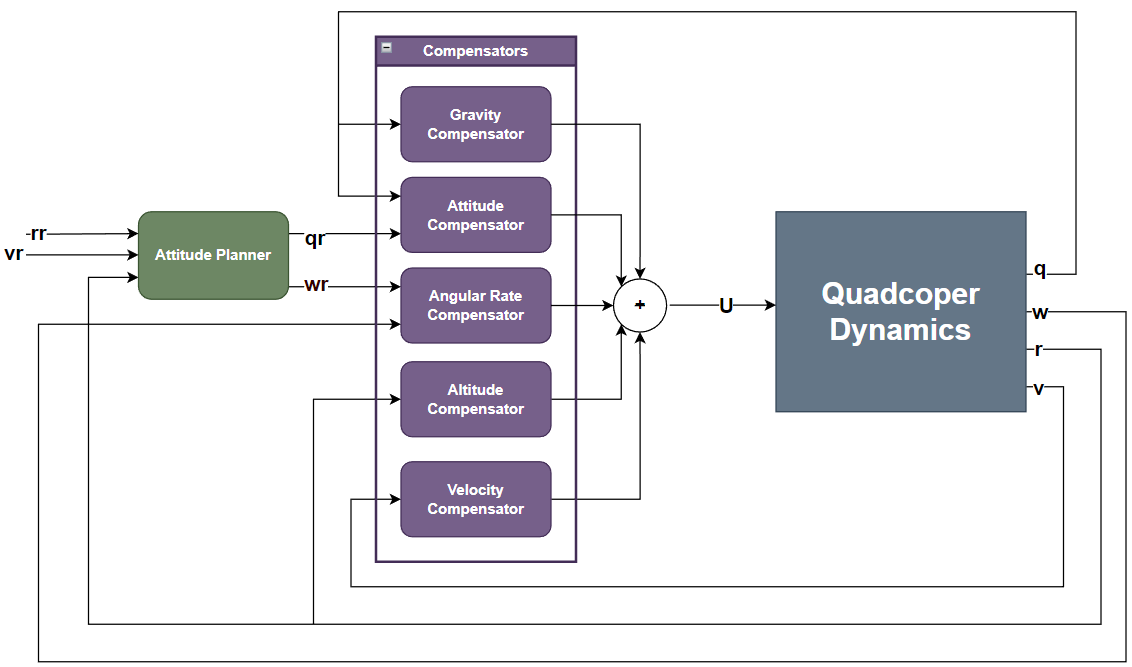

**Best Gains:** Rufous_og_controller(Kt, mass, g, q, 75, 100, 0.08, 0.5, 15);

### PD-PD-Gravity Control Law

For $v_r ,\; \omega_r = 0$

mag_range = [1e-2 1e4];
freq_range = [1e-10 1e3];

[Kref, Kfb, ~] = Rufous_og_controller(Kt, mass, g, q_hist(:,i), 75, 100, 0.08, 0.5, 15);
L = G * Kfb * Kref;
S = 1 / (eye(12) + L);
T = minreal(L * S);

20 states removed.



WI = makeweight(0.01, [1, 1], 10);

Hinf_norm_s = norm(S, 'inf')

Hinf_norm_s = 10.5497

Hinf_norm_t = norm(T, 'inf')

Hinf_norm_t = Inf

Hinf_norm_n11 = norm(WI * T, 'inf')

Hinf_norm_n11 = Inf

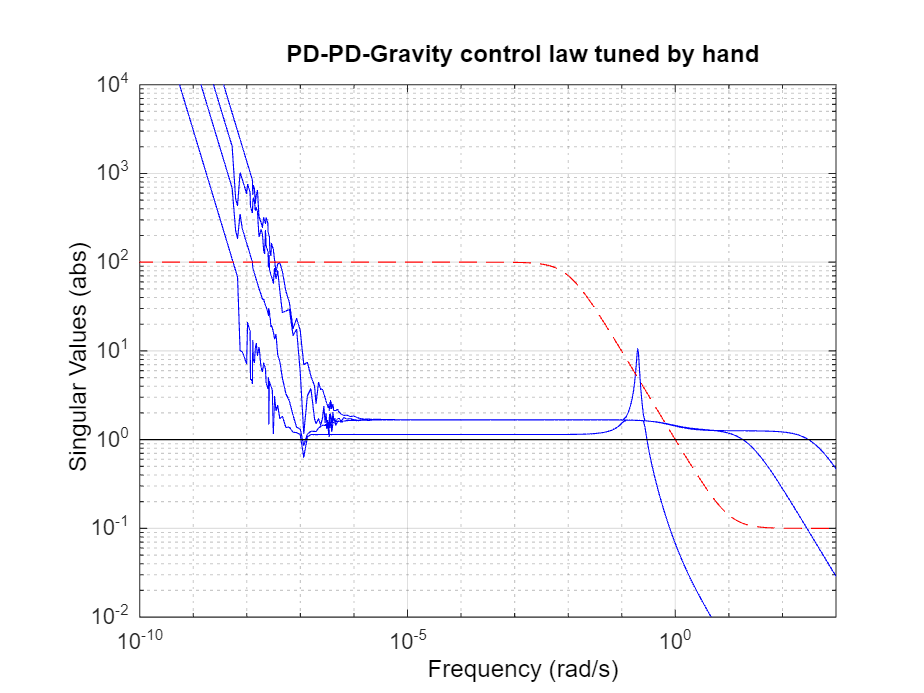


figure, hold on
h = sigmaplot(T, 'b', WI^-1, 'r--');
plot(freq_range, [1, 1], 'k');
setoptions(h, 'MagUnits', 'abs', 'MagScale', 'log', 'Xlim', freq_range, 'Ylim', mag_range);
title("PD-PD-Gravity control law tuned by hand")

## Simulation

This simulation tests Rufous_OG_controller a PD-PD-Gravity compensator. 

Could have better reference attitude tracking. Currently the controller uses the kinematics to damp translational velocity. The velocity should be used in the calculation of the attitude reference not directly computing actuator control. There are issues with the quad wanting to track a reference but the translational velocity damping term won't allow it (which is for the best sometimes). Everything feels pretty sketchy and according to all the analysis the attitude and angular rate system should not be stable... 

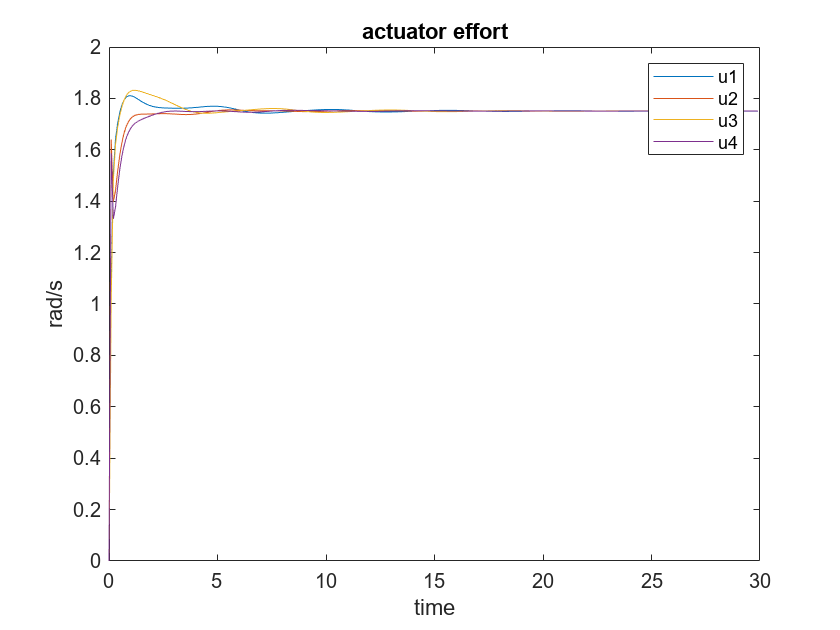

max_time = 30;
n_samples = max_time / 0.001;
t_space = linspace(0, max_time, n_samples);

dt = max_time / n_samples;

% histories
u_hist = zeros(4, n_samples);
r_hist = zeros(3, n_samples);
rdot_hist = zeros(3, n_samples);
rddot_hist = zeros(3, n_samples);
q_hist = zeros(3, n_samples);
qr_hist = zeros(3, n_samples);
omega_hist = zeros(3, n_samples);
omegadot_hist = zeros(3, n_samples);

% extracts qr from a reference
qr_ext = [0 0 0 0 0 0 1 0 0 0 0 0; 0 0 0 0 0 0 0 1 0 0 0 0; 0 0 0 0 0 0 0 0 1 0 0 0];

% set initial conditions
% Currently set up to show the quad being far from the reference in every
% direction (-theta and -omegax for maximum testage)
r_r = [1; 0; 1];
r_hist(3, 1) = 1;
q_hist(1, 1) = -0.17;
q_hist(3, 1) = -0.6 * pi;
omega_hist(1, 1) = -0.1;
u_hist(:, 1) = zeros(4, 1);

for i = 1:(n_samples - 1)
	% step dynamics
	[dr, ddr, dq, do] = Rufous_Dynamics(rdot_hist(:,i), q_hist(:,i), omega_hist(:,i), u_hist(:,i), Kt, mass, g, l, Ib);

	% update control
	R = [r_r; 0; 0; 0; 0; 0; 0; 0; 0; 0];
	X = [r_hist(:, i); rdot_hist(:,i); q_hist(:,i); omega_hist(:,i)];
	[Kref, Kfb, Kff] = Rufous_og_controller(Kt, mass, g, q_hist(:,i), 75, 100, 0.08, 0.5, 15);
	Katt = Kfb(:, 7:9);

	% update states
	u_hist(:, i + 1) = Kff + (Kfb * Kref * (R - X));
	r_hist(:, i + 1) = r_hist(:, i) + (dr * dt);
	rdot_hist(:, i + 1) = rdot_hist(:, i) + (ddr * dt);
	q_hist(:, i + 1) = wrap_angle(q_hist(:, i) + (dq * dt));
	qr_hist(:, i + 1) = -qr_ext * (Kref * (R - X));
	omega_hist(:, i + 1) = omega_hist(:, i) + (do * dt);

	% Sample Lyapunov
	V = Rufous_Lyapunov(q_hist(1, i+1), q_hist(2, i+1), q_hist(3, i+1), omega_hist(1, i+1), omega_hist(2, i+1), omega_hist(3, i+1), qr_hist(:, i+1), Ib, Katt);

	if V > 1e4 % instability catcher, sorta works, not the way it should though (use Vdot instead)
		fprintf("Breaking for Lyapunov value %d at %i", V, i);
		fprintf("Omega %d %d %d", omega_hist(1, i), omega_hist(2, i), omega_hist(3, i));
		break;
	end

	if r_hist(3, i + 1) <= 0 % ground
		r_hist(3, i + 1) = 0;
		rdot_hist(3, i + 1) = max(0, rdot_hist(3, i + 1));
	end
end

figure
plot(t_space(1:100:end), max(u_hist(:, 1:100:end), [0; 0; 0; 0]))
title("actuator effort")
xlabel("time")
ylabel("rad/s")
legend("u1", "u2", "u3", "u4");

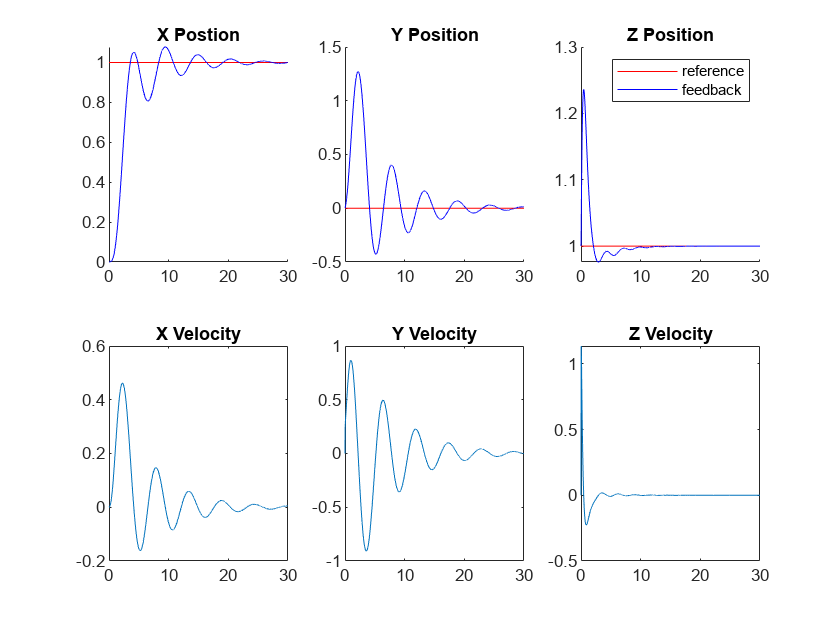


figure
title("Position history")
position_titles = ["X Postion" "Y Position" "Z Position" "X Velocity" "Y Velocity" "Z Velocity"];
plot_vectors(t_space, r_hist, rdot_hist, ones(size(r_hist)) .* r_r, position_titles, 5);

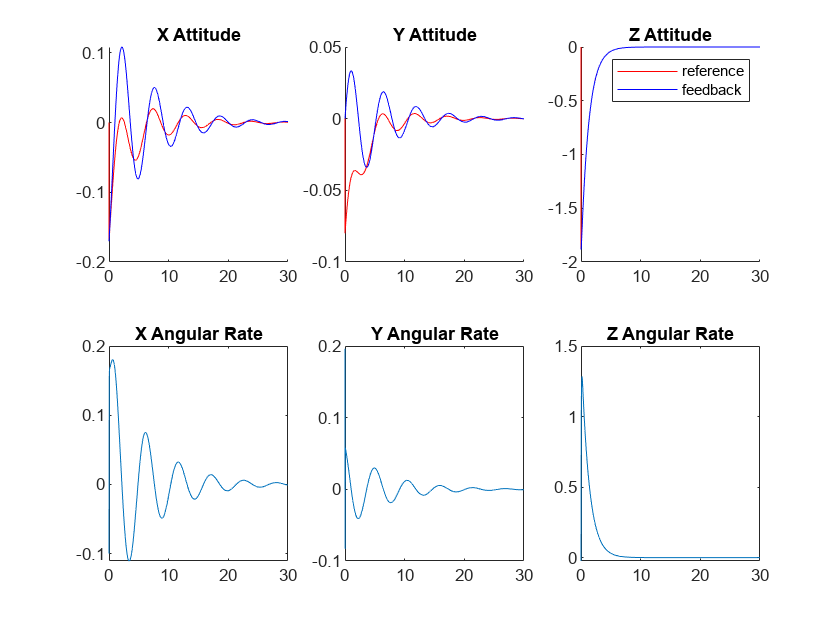


figure
title("Attitude history")
attitude_titles = ["X Attitude" "Y Attitude" "Z Attitude" "X Angular Rate" "Y Angular Rate" "Z Angular Rate"];
plot_vectors(t_space, q_hist, omega_hist, qr_hist, attitude_titles, 1);